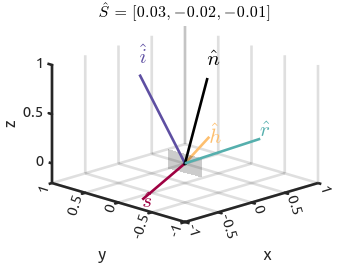

% Testbed for visualizing polarization state-aware ray tracing
% N. Laxague 2024

figure_style_live_script

violet = [0.368627000000000	0.309804000000000	0.635294000000000];
teal = [0.332026000000000	0.684967000000000	0.678431333333333];
champagne = [0.993464000000000	0.747712333333333	0.435294000000000];
ruby_port = [0.619608000000000	0.00392200000000000	0.258824000000000];

d_ang = 10;

% Sky dome (ray origin) parameters
sky_dome_azimuth = -30;
sky_dome_polar = 30;
sky_z = 100;

% Define surface normal vector
slope_x = 0.01;
slope_y = 0.37;

[ray_inc,ray_refl,h_inc,s,S_refl,N0,x_face,y_face,z_face] = ray_tracing_helper(sky_dome_azimuth,sky_dome_polar,sky_z,slope_x,slope_y);

% Plot reflection figure
figure(111);clf
hold on
f = fill3(x_face,y_face,z_face,'k');
plot3(-[ray_inc(1) 0],-[ray_inc(2) 0],-[ray_inc(3) 0],'-','linewidth',2)
plot3([ray_refl(1) 0],[ray_refl(2) 0],[ray_refl(3) 0],'-','linewidth',2)
plot3([h_inc(1) 0],[h_inc(2) 0],[h_inc(3) 0],'-','linewidth',2)
plot3([s(1) 0],[s(2) 0],[s(3) 0],'-','linewidth',2)
plot3([N0(1) 0],[N0(2) 0],[N0(3) 0],'k-','linewidth',2)
plot3(0,0,0,'k.','markersize',10)
hold off
f.FaceAlpha = 0.2;
f.LineStyle = 'none';
view([-45 25])
xlim([-1 1]);ylim([-1 1]);zlim([-0.2 1])
% xlabel('$x$','Interpreter','latex')
% ylabel('$y$','Interpreter','latex')
% zlabel('$z$','Interpreter','latex')
xlabel('x')
ylabel('y')
zlabel('z')
title(['$\hat{S} = [' sprintf('%0.2f',S_refl(1)) ', ' sprintf('%0.2f',S_refl(2)) ', ' sprintf('%0.2f',S_refl(3)) ']$'],'Interpreter','latex')
%set(gca,'FontSize',14)
text(-ray_inc(1),-ray_inc(2),-ray_inc(3)*1.2,'$\hat{i}$','Color',violet,'Interpreter','LaTeX','FontSize',16,'FontWeight','bold')
text(ray_refl(1),ray_refl(2),ray_refl(3)*1.2,'$\hat{r}$','Color',teal,'Interpreter','LaTeX','FontSize',16,'FontWeight','bold')
text(h_inc(1),h_inc(2),h_inc(3)*1.2,'$\hat{h}$','Color',champagne,'Interpreter','LaTeX','FontSize',16,'FontWeight','bold')
text(s(1),s(2),s(3)*1.2,'$\hat{s}$','Color',ruby_port,'Interpreter','LaTeX','FontSize',16,'FontWeight','bold')
text(N0(1),N0(2),N0(3)*1.2,'$\hat{n}$','Color',[0 0 0],'Interpreter','LaTeX','FontSize',16,'FontWeight','bold')
ax = gca;
ax.XTick = -1:0.5:1;
ax.YTick = -1:0.5:1;
ax.ZTick = -1:0.5:1;

function [ray_inc,ray_refl,h_inc,s,S_refl,N0,x_face,y_face,z_face] = ray_tracing_helper(sky_dome_azimuth,sky_dome_polar,sky_z,slope_x,slope_y)

% Incident ray properties
% S_inc = [1;0;0;0];
S_inc1 = 1;S_inc2=0;S_inc3=0;S_inc4=0;
ray_inc_x = sind(sky_dome_azimuth)*tand(sky_dome_polar)*sky_z;
ray_inc_y = cosd(sky_dome_azimuth)*tand(sky_dome_polar)*sky_z;
ray_inc_z = 0*ray_inc_x + sky_z;

% Establish position of surface facet
X = 0;
Y = 0;
Z = 0;

N0 = [-slope_x;-slope_y;1];
N0 = N0/norm(N0);

% Construct surface facet object
x_face = [-1 0 1 0]*0.25;
y_face = [0 -1 0 1]*0.25;
z_face = slope_x*x_face + slope_y*y_face;

% Compute incident ray
ray_inc = [X Y Z]' - [ray_inc_x ray_inc_y ray_inc_z]';ray_inc = ray_inc/norm(ray_inc);

% Compute incidence angle with respect to surface facet
n = 1.34;
theta_i = abs(90-acosd(ray_inc'*N0));
theta_t = asind(sind(theta_i)./n);

% Compute reflected ray vector
ray_refl = (ray_inc - (2*ray_inc'*N0).*N0);

% Compute h and s vectors (Mobley 2015)
h_inc = cross([0;0;1],ray_inc);
h_inc = h_inc/norm(h_inc);
s = cross(ray_inc,N0);
s = s/norm(s);

h_cross_s = cross(h_inc,s);
alpha_ang = acosd(h_inc'*s);
antiparallel_inds = h_cross_s(3)*ray_inc(3) < 0;
alpha_ang(antiparallel_inds) = 360 - abs(alpha_ang(antiparallel_inds));

c2a = cosd(2*alpha_ang);
s2a = sind(2*alpha_ang);

% Rotation matrix, Stokes vector
% R = [1,0,            0,             0;
%     0,cosd(2*alpha_ang),-sind(2*alpha_ang),0;
%     0,sind(2*alpha_ang),cosd(2*alpha_ang), 0;
%     0,0,            0,             1];

% Mueller matrix for reflection off surface, KA89
alpha = 1/2*(tand(theta_i-theta_t)./tand(theta_i+theta_t)).^2;
eta = 1/2*(sind(theta_i-theta_t)./sind(theta_i+theta_t)).^2;
gamma_Re = (tand(theta_i-theta_t).*sind(theta_i-theta_t))./(tand(theta_i+theta_t).*sind(theta_i+theta_t));

% R_AM = [alpha+eta,alpha-eta,0,       0;
%     alpha-eta,alpha+eta,0,       0;
%     0,        0,        gamma_Re,0;
%     0,        0,        0,       gamma_Re];

% Compute reflected Stokes vector
% S_refl = R*R_AM*S_inc;

S_refl_0 = S_inc1*(alpha+eta)+S_inc2*(alpha-eta);
S_refl_1 = S_inc1*c2a.*(alpha-eta)+S_inc2*c2a.*(alpha+eta)-S_inc3*s2a.*gamma_Re;
S_refl_2 = S_inc1*s2a.*(alpha-eta)+S_inc2*s2a.*(alpha+eta)+S_inc3*c2a.*gamma_Re;
S_refl_3 = S_inc4*gamma_Re;

S_refl = [S_refl_0; S_refl_1; S_refl_2; S_refl_3];

end